# ROC Curves

Sam Coleman

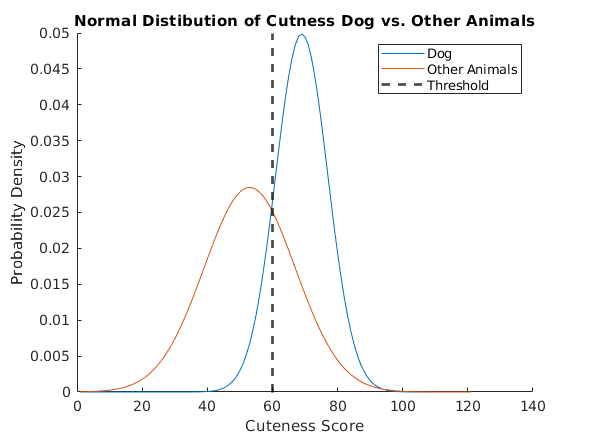

%calculate distributions
x = 0:120;
dog_norm = makedist("Normal", "mu", 68, "sigma", 8);
animal_norm = makedist("Normal", "mu", 52, "sigma", 14);

%determine threshold
thresh = 60;

%plot
figure();
hold on;
plot(dog_norm.pdf(x));
plot(animal_norm.pdf(x));
xline(thresh, 'k--', 'LineWidth', 2);
xlabel('Cuteness Score')
ylabel('Probability Density')
title('Normal Distibution of Cutness Dog vs. Other Animals')
legend('Dog', 'Other Animals', 'Threshold')
hold off;

If cost of misclassifying dog as not a dog was higher than other animal as a dog means we want to minimize false negatives. The threshold would move to the left.

%Estimate accuracy with threshold at 60
dog_accuracy = 1-cdf(dog_norm, thresh)

dog_accuracy = 0.4207

animal_accuracy = cdf(animal_norm, thresh)

animal_accuracy = 358.0727

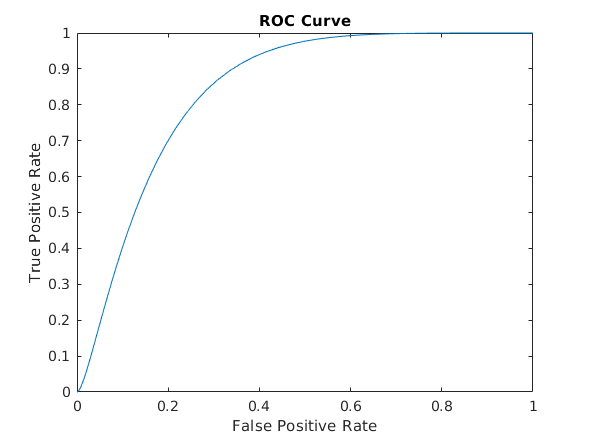

%Generate and plot ROC Curve
%false positive x, true positive y
%false positie is other animal classified as dog
%true positive is dog classified as dog
range = 0:100;
rates = ones([length(range),2]); %col1: fpr col2: tpr
for i = range 
    rates(i+1,1) = 1-cdf(animal_norm, i);
    rates(i+1, 2) = 1-cdf(dog_norm, i);
end
plot(rates(:,1), rates(:,2))
title("ROC Curve");
xlabel("False Positive Rate")
ylabel("True Positive Rate")

%calculating without forloop
rates_1 = [1-cdf(animal_norm, range), 1-cdf(dog_norm, range)];
plot(rates(:,1), rates(:,2))
title("ROC Curve");
xlabel("False Positive Rate")
ylabel("True Positive Rate")